# Modelo SEIRS

**Universidad eafit**

**Primer Semestre 2024**

**Sistemas lineales**

**Carlos M. Veléz S.**

**Luis M. Martinez G.**

**Sebastian A. Amaya C.**

## 1.El Modelo SIERS

El modelo SEIRS, una piedra angular de la epidemiología, divide las poblaciones en compartimentos susceptibles (S), expuestos (E), infecciosas (I), recuperadas (R) y nuevamente susceptibles (S), lo que proporciona un enfoque estructurado para estudiar la dinámica de transmisión de enfermedades. A través de ecuaciones diferenciales, rastrea el movimiento de los individuos entre estos compartimentos a lo largo del tiempo, lo que refleja las transiciones de la susceptibilidad a la exposición, la infección y, en última instancia, la recuperación o la susceptibilidad nuevamente.

La versatilidad de este modelo se extiende a diversas aplicaciones, incluida la predicción de la propagación de enfermedades, la evaluación de estrategias de intervención y la optimización de la asignación de recursos durante los brotes. Al simular diferentes escenarios, los investigadores y los responsables de la formulación de políticas pueden anticipar la trayectoria de las enfermedades infecciosas, evaluar la eficacia de las medidas de control y tomar decisiones informadas para mitigar su impacto en la salud pública.

Su marco matemático proporciona información sobre las tasas de transmisión, los períodos de latencia y la dinámica de la inmunidad, lo que permite a las partes interesadas implementar medidas proactivas y gestionar eficazmente los brotes de enfermedades dentro de las poblaciones.

### 1.1.Descripcion del modelo

La mayoría de las descripciones matemáticas de la dinámica poblacional de las enfermedades infecciosas se basan en la capacidad de dividir la población en compartimentos discretos que no se superponen para asi estudiar el flujo de los inidividuos atravez de las diferentes clasificaiones. Para este Modelo se estudian 4 compartimientos:

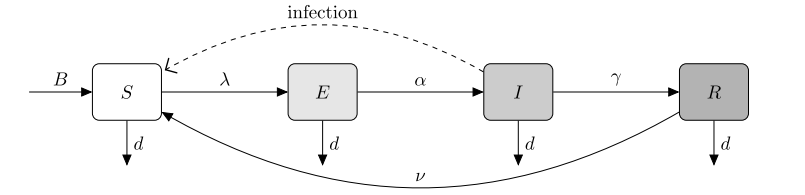

#### figura1

La figura 1 nos brinda un "esquema" del modelo y de la interaccion de entre las poblaciones del modelo de esta practica, es importante hacer clara ciertas consideraciones del modelo, primero, tomando una visión centrada en el patógeno, categorizamos al huésped (persona) por su estado con respecto al patógeno,Como las siglas del modelo indican los compartimientos en los que se divide la poblacion son:

- Suceptibles(S):Individuos que no han sido infectados por la enfermedad y que pueden contraerla si entran en contacto con personas infectadas

- Infeciosas(I):Individuos actualmente infectados con la enfermedad y que pueden transmitirla a otros susceptibles.

- Recuperados(R):Individuos que han sido infectados previamente pero ya se han recuperado de la enfermedad. Son inmunes y pueden volver a contraer la enfermedad.

- Expuestos(E): Individuos que han sido infectados con una enfermedad pero que aún no son contagiosos.

- Poblacion total (N): es la suma de todas las poblaciones anteriores

Ademas podemos observar que se considera una poblacion aislada y que la enfermdad modelada no es mortal, es decir la unica entrada de nuevos integrantes es mediante nacimientos  y la unica salida es mediante muerte por causas ajenas al patojeno, en la siguiente seccion se explicara con mayor detalle la dinamica del modelo.

### 1.2.VARIABLES Y PÁRAMETROS DEL MODELO

Se puede observar que se usan varios parametros para regular el flujo entre las diferentes poblaciones, acontinuacion se da una descripcion de de estas:

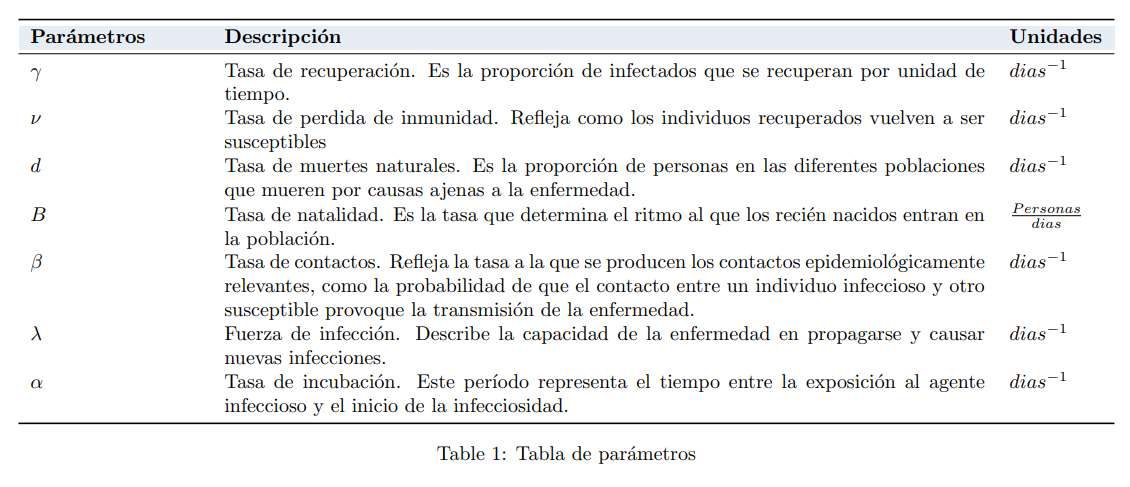

#### figura 2

### 1.3 Ecuaciones del modelo

Considerando la clasifiacion de la poblacion previamente establecida, las ecuaciones no lineales del modelo se pueden describir de la siguiente manera:

La población susceptible `(S)` varía con el tiempo `(t)`, aumentando con la llegada de recién nacidos `(B) `y los recuperados que pierden su inmunidad `(νR)`, y disminuyendo con los susceptibles que son infectados `(-λS)` y los que han muerto por causas naturales `(-dS)`.


$$\frac{\mathrm{dS} }{\mathrm{d} t}=B+\nu R-\lambda S-dS$$
  

La población expuesta `(E)` varía con el tiempo `(t)`, incrementando con los susceptibles que han sido infectados `(λS)` y disminuyendo con los individuos expuestos que incuban la enfermedad (se vuelven infecciosos) `(-αE)` y los expuestos que han fallecido por causas naturales `(-dE)`.


$$\frac{\mathrm{d} E}{\mathrm{d} t}=\lambda S -\alpha E-dE$$
  

La población infectada `(I)` varía con el tiempo `(t)`, aumentando con los individuos expuestos que incuban la enfermedad (se vuelven infecciosos) `(αE)`, y reduciendo con aquellos infectados que se han recuperado `(-γI) `o han fallecido por causas naturales `(-dI)`.


$$\frac{\mathrm{d} I }{\mathrm{d} t}=\alpha E - \gamma I-dI$$
 

La población recuperada `(R)` varía con el tiempo `(t)`, incrementando con los individuos infectados que se han recuperado `(γI)` y reduciendo con aquellos recuperados que pierden su inmunidad y se vuelven susceptibles de nuevo `(-νR)` y los recuperados que han fallecido por causas naturales `(-dR)`.


$$\frac{\mathrm{d} R }{\mathrm{d} t}= \gamma I-\nu R-dR$$


Debido a que el tamaño de nuestra poblacion es variable el valor de la fuerza de infeccion **(λ) **se actualiza constantemente


$$\lambda=\frac{\beta I}{N}$$


El modelo completo se compone de las siguientes 5 ecuaciones:

**(1) **$\frac{\mathrm{dS} }{\mathrm{d} t}=B+\nu R-\lambda S-dS$            

**(2) **$\frac{\mathrm{d} E}{\mathrm{d} t}=\lambda S -\alpha E-dE$                

**(3) **$\frac{\mathrm{d} I }{\mathrm{d} t}=\alpha E - \gamma I-dI$                 

**(4) **$\frac{\mathrm{d} R }{\mathrm{d} t}= \gamma I-\nu R-dR$                  

**(5) **$\lambda=\frac{\beta I}{N}$                                    

### 1.4 hipotesis

acontinuacion se plantean hipotsis del comprtamiento del sistema al relalizar cambios en los parametros ***β***, `γ` y` ν`:

- Reducciones periódicas drásticas en β (cuarentenas): Se espera una disminución dramática en el número de infectados debido a la reducción en la tasa de transmisión durante el período de cuarentena.

- Variación estacional en β: Si la tasa de transmisión (β) oscila con valores sinusoidales que simulan las estaciones del año, se espera una convergencia más lenta de la enfermedad. Las infecciones deberían disminuir al principio del año cuando la tasa de transmisión sea baja, y aumentar al final del año cuando la tasa de transmisión sea alta.

- Aumentos abruptos en β (nueva cepa del patógeno): Se predice un aumento en la población infectada y una convergencia más rápida hacia la propagación del patógeno debido a la mayor tasa de transmisión.

- Incremento de ν: A medida que la tasa de pérdida de inmunidad aumenta, se espera un crecimiento en la población de infectados, ya que la inmunidad adquirida disminuye con mayor rapidez.

- Incremento de γ: Con un aumento en la tasa de recuperación, se anticipa una mayor población recuperada y una disminución en la población infectada, ya que los individuos se recuperan más rápidamente. 

## 2.Metodos

En esta sección de métodos, se proporcionará una explicación de como se realiza la verificacion del sistema en Simulink. Se describirá  el proceso de realización de cada prueba en Simulink, desde la configuración hasta la interpretación de los resultados, ofreciendo una visión general del enfoque metodológico utilizado en este estudio.

### 2.1 MODELO VERIFICADO DEL SISTEMA EN SIMULINK

Se Realiza la verificacion del modelo al recrear la figura 3 de  [1] que representa el comportamiento del modelo SIERS, para cumplir este objetivo se realiza la simulacion con parametros que se enlistaran proximamente y se compara la simulacion con la grafica de referencia.

- ***β***=0.2

- `ν`=0.001

- ***α***=0.1

- `γ`=0.1

- `d`=0.0001

- `B`=0.0001

### 2.2 Resumen de los pasos

Debido a que el modelo no tiene entradas, se añade una entrada artificial mendiante un cambio en el parametro  ***β, ***ademas se realizan variaciones individuales en los parametros `γ` y `v`  con el objetivo de simular cambios en el sistema esto representaria posibles politcas implementadas sobre la poblacion como  por ejemplo cuarentenas(o la ausencia de estas). En el proceso de simulación en SIMULINK, se implementaron meticulosamente tres enfoques clave:

- Se realizan 3 cambios sobre el parametro ***β, ***sumando señales de tipo escalon, seno  y pulso, realizando un aumento de ***β ***`en dia 500 en el caso del escalon.El seno se utliza para simular el efecto de las estaciones del año sobre los valores de `***β *** ` y en el caso del pulso disminuyendo el valor de `***β ***drasticamente en periodos de 23 dias` ,` se extraen los parametros y se grafica el cambio sobre la poblacion infectada.

- Se realizan simulaciones variando el parameto `v` (tasa de perdida de inmunidad) para observar los efectos de tener una poblacion con mayor retencion de la inmunidad, esto puede representar  la Implementación de políticas de salud pública que promuevan estilos de vida saludables y refuercen el sistema inmunológico de la población. Se grafican los cambios sobre la poblacion infectada , la poblacion suceptible y se construye una tabla de comaparacion de los parametros con las poblaciones en el dia 500.

- Se realizan simulaciones variando el parámetro `γ` (tasa de recuperación) para observar los efectos en la velocidad de recuperación de los pacientes infectados y en la dinámica de la propagación de la enfermedad. Esto puede representar la implementación de políticas de salud pública que amplíen la atención de los pacientes infectados. Se grafican los cambios sobre la poblacion infectada , la poblacion suceptible y se construye una tabla de comaparacion de los parametros con las poblaciones en el dia 500.

## 3. Resultados

dir_modelo = "SEIRS_2.slx";

### 3.1. Verificacion de Codigo

T=2500; 
x=zeros(1,6);
x(1)=0.0001; %B
x(2)=0.0001; %d
x(3)=0.1; %alpha_
x(4)=0.1; %gamma_
x(5)=0.2; %beta_
x(6)=0.001; %nu_
%N0_=[1-1e-6 1e-6 0 0]; 
beta_U=timetable(seconds(0),0);
simulacion_1_verificacion=sim(dir_modelo);

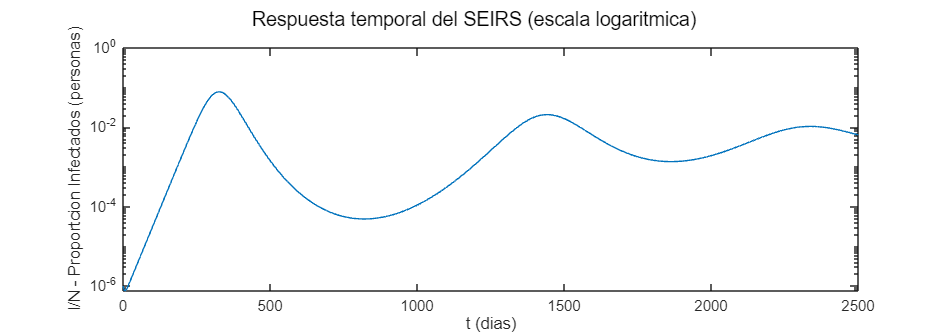

tiempo=simulacion_1_verificacion.tout;
infectados=simulacion_1_verificacion.Infectados;

h1 = figure;
subplot(1,1,1), plot(tiempo,infectados), xlabel('t (dias)'), ylabel('I/N - Proportcion Infectados (personas)')
set(h1,'Units','normalized','Position',[0 0 0.8 0.5]);
yscale log
sgtitle('Respuesta temporal del SEIRS (escala logaritmica)')

### 3.2. Cambios Entradas

#### 3.2.1 Solucion con un cambio de β (pulso)

Observar los efectos al relizar politacas que reduzcan los contactos entre la poblacion (distanciamiento social, uso de tapabocas, cuarentenas, etc.)

T=2500;
B=0.0001;
d=0.0001;
alpha_=0.1;
gamma_=0.1;
nu_=0.001;
beta_=0.2;
N0_=[1-1e-6 1e-6 0 0];

time = (0:0.01:T)';
beta_U = timetable(seconds(time),(time>=500)*0.2); sim_1_beta=sim(dir_modelo); I1 = sim_1_beta.Infectados; t1 = sim_1_beta.tout; beta1 = beta_;

beta_U = timetable(seconds(time),-sin(time*2*pi/365)*0.2); sim_2_beta=sim(dir_modelo); I2 = sim_2_beta.Infectados; t2 = sim_2_beta.tout; beta2 = beta_;

beta_U = timetable(seconds(time),(mod(time,50)>=27)*(-beta_)); sim_3_beta=sim(dir_modelo); I3 = sim_3_beta.Infectados; t3 = sim_3_beta.tout; beta3 = beta_;

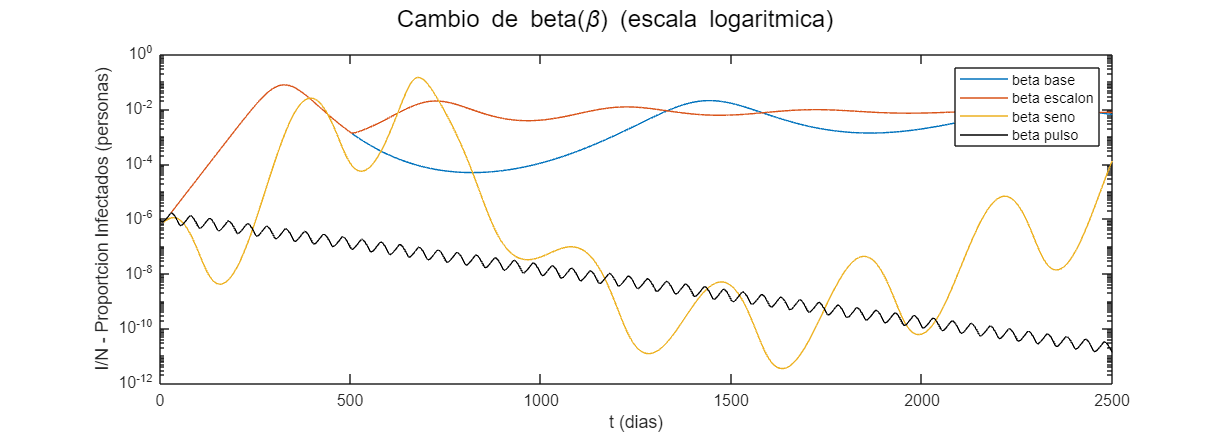


h2 = figure;
subplot(1,1,1), plot(tiempo,infectados,t1,I1,t2,I2,t3,I3,'k'), xlabel('t (dias)'), ylabel('I/N - Proportcion Infectados (personas)')
set(h2,'Units','normalized','Position',[0 0 0.8 0.5]);
yscale log
legend({'beta base','beta escalon','beta seno','beta pulso'})
sgtitle('Cambio de beta(\beta) (escala logaritmica)')

### 3.3. Variacion de parametros

#### 3.3.1. Soluciones cambiando ν

Observar el efecto negativo de aumentar ν (tasa de perdida de inmunidad)

T=2500;
B=0.0001;
d=0.0001;
alpha_=0.1;
gamma_=0.1;
beta_=0.2;
beta_U=timetable(seconds(0),0);
N0_=[1-1e-6 1e-6 0 0];
nu_=0.001; sim_1_nu=sim(dir_modelo);   nu1 = nu_;

nu_=0.002; sim_2_nu=sim(dir_modelo);  nu2 = nu_;

nu_=0.003; sim_3_nu=sim(dir_modelo); nu3 = nu_;

nu_=0.004; sim_4_nu=sim(dir_modelo);  nu4 = nu_;

nu_=0.005; sim_5_nu=sim(dir_modelo);  nu5 = nu_;

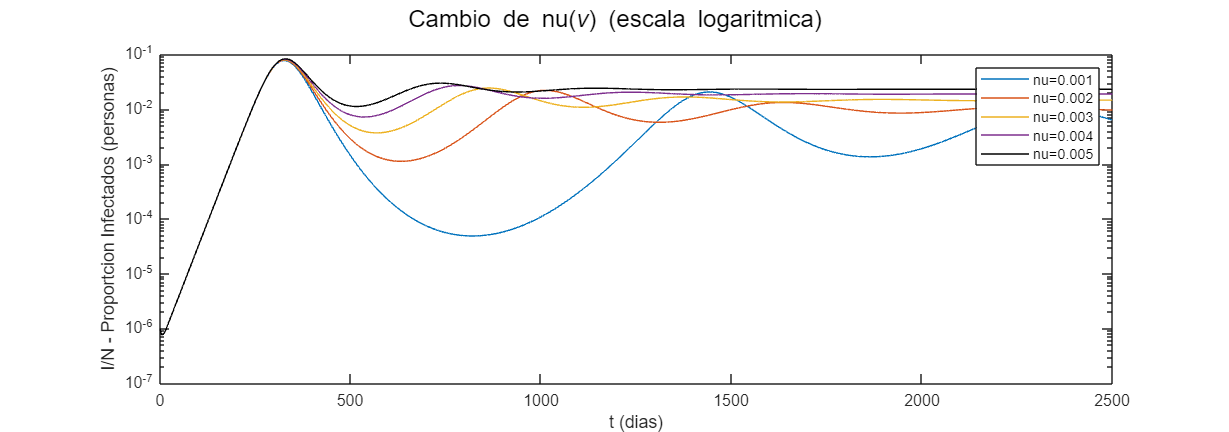

 
h1 = figure;
subplot(1,1,1), plot(sim_1_nu.tout,sim_1_nu.Infectados,sim_2_nu.tout,sim_2_nu.Infectados,sim_3_nu.tout,sim_3_nu.Infectados,sim_4_nu.tout,sim_4_nu.Infectados,sim_5_nu.tout,sim_5_nu.Infectados,'k'), xlabel('t (dias)'), ylabel('I/N - Proportcion Infectados (personas)')
set(h1,'Units','normalized','Position',[0 0 0.8 0.5]);
yscale log
legend({['nu=' num2str(nu1)],['nu=' num2str(nu2)],['nu=' num2str(nu3)],['nu=' num2str(nu4)],['nu=' num2str(nu5)]})
sgtitle('Cambio de nu(\nu) (escala logaritmica)')

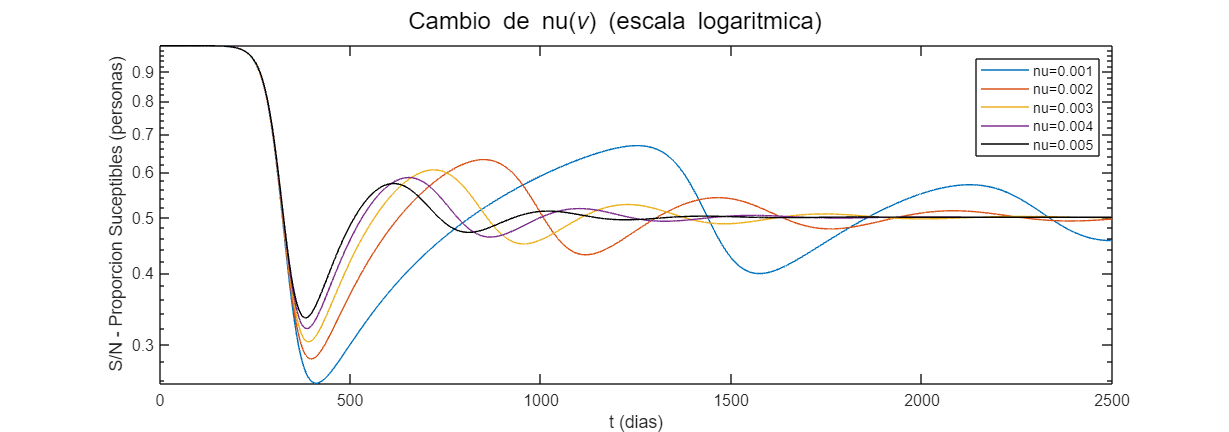

h1 = figure;
subplot(1,1,1), plot(sim_1_nu.tout,sim_1_nu.Suceptibles,sim_2_nu.tout,sim_2_nu.Suceptibles,sim_3_nu.tout,sim_3_nu.Suceptibles,sim_4_nu.tout,sim_4_nu.Suceptibles,sim_5_nu.tout,sim_5_nu.Suceptibles,'k'), xlabel('t (dias)'), ylabel('S/N - Proporcion Suceptibles (personas)')
set(h1,'Units','normalized','Position',[0 0 0.8 0.5]);
yscale log
legend({['nu=' num2str(nu1)],['nu=' num2str(nu2)],['nu=' num2str(nu3)],['nu=' num2str(nu4)],['nu=' num2str(nu5)]})
sgtitle('Cambio de nu(\nu) (escala logaritmica)')

index=50001;
vals_nu=[0.001;0.002;0.003;0.004;0.005;];
vals_infectados=log([sim_1_nu.Infectados(index);sim_2_nu.Infectados(index);sim_3_nu.Infectados(index);sim_4_nu.Infectados(index);sim_5_nu.Infectados(index)]);
vals_suceptibles=log([sim_1_nu.Suceptibles(index);sim_2_nu.Suceptibles(index);sim_3_nu.Suceptibles(index);sim_4_nu.Suceptibles(index);sim_5_nu.Suceptibles(index)]);
table(vals_nu,vals_infectados,vals_suceptibles)

ans = 5×3 table
    vals_nu    vals_infectados    vals_suceptibles
    _______    _______________    ________________

     0.001         -6.5542             -1.2019    
     0.002         -5.8544            -0.99895    
     0.003         -5.2948            -0.86714    
     0.004         -4.8425            -0.77944    
     0.005          -4.474             -0.7212    


#### 3.3.2 Soluciones numéricas con un cambio de γ

Observar el efecto positivo de aumentar γ (tasa de recuperación)

T=2500;
B=0.0001;
d=0.0001;
alpha_=0.1;
nu_=0.001;
beta_U=timetable(seconds(0),0);
N0_=[1-1e-6 1e-6 0 0];
gamma_ = 0.02; sim_1_gamma=sim(dir_modelo);   gamma1 = gamma_;

gamma_ = 0.03; sim_2_gamma=sim(dir_modelo);   gamma2 = gamma_;

gamma_ = 0.04; sim_3_gamma=sim(dir_modelo);   gamma3 = gamma_;

gamma_ = 0.05; sim_4_gamma=sim(dir_modelo);   gamma4 = gamma_;

gamma_ = 0.078; sim_5_gamma=sim(dir_modelo);   gamma5 = gamma_;

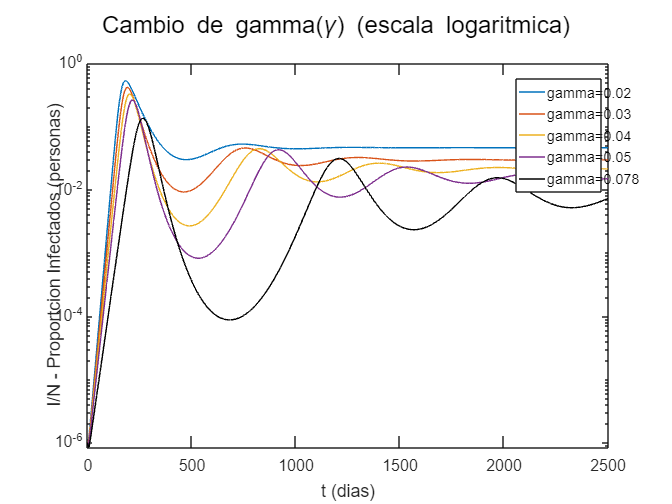


h3 = figure;
subplot(1,1,1), plot(sim_1_gamma.tout,sim_1_gamma.Infectados,sim_2_gamma.tout,sim_2_gamma.Infectados,sim_3_gamma.tout,sim_3_gamma.Infectados,sim_4_gamma.tout,sim_4_gamma.Infectados,sim_5_gamma.tout,sim_5_gamma.Infectados,'k'), xlabel('t (dias)'), ylabel('I/N - Proportcion Infectados (personas)')
set(h3,'Units','normalized','Position',[0 0 0.8 0.5]);
yscale log
legend({['gamma=' num2str(gamma1)],['gamma=' num2str(gamma2)],['gamma=' num2str(gamma3)],['gamma=' num2str(gamma4)],['gamma=' num2str(gamma5)]})
sgtitle('Cambio de gamma(\gamma) (escala logaritmica)')

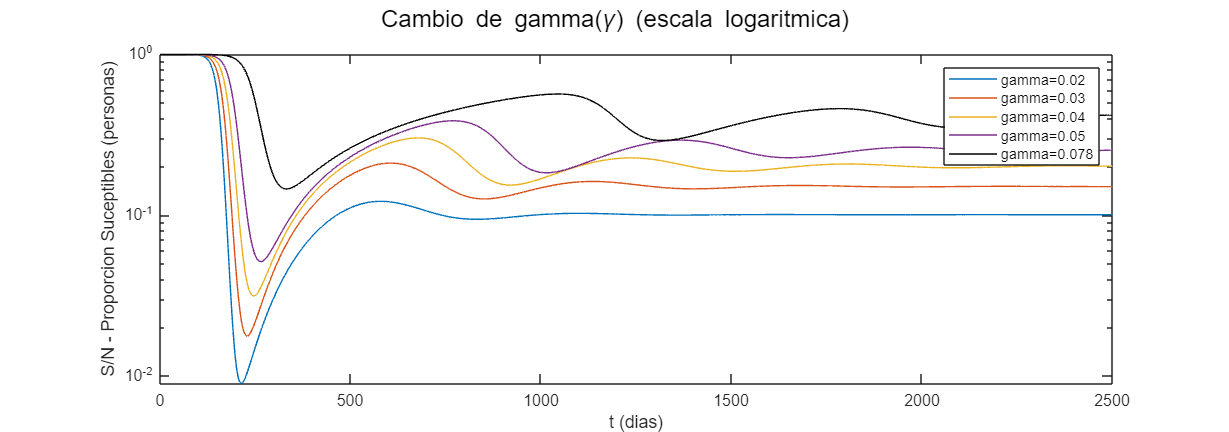

h3 = figure;
subplot(1,1,1), plot(sim_1_gamma.tout,sim_1_gamma.Suceptibles,sim_2_gamma.tout,sim_2_gamma.Suceptibles,sim_3_gamma.tout,sim_3_gamma.Suceptibles,sim_4_gamma.tout,sim_4_gamma.Suceptibles,sim_5_gamma.tout,sim_5_gamma.Suceptibles,'k'), xlabel('t (dias)'), ylabel('S/N - Proporcion Suceptibles (personas)')
set(h3,'Units','normalized','Position',[0 0 0.8 0.5]);
yscale log
legend({['gamma=' num2str(gamma1)],['gamma=' num2str(gamma2)],['gamma=' num2str(gamma3)],['gamma=' num2str(gamma4)],['gamma=' num2str(gamma5)]})
sgtitle('Cambio de gamma(\gamma) (escala logaritmica)')

index=50001;
vals_gamma=[0.02;0.03;0.04;0.05;0.078;];
vals_infectados=log([sim_1_gamma.Infectados(index);sim_2_gamma.Infectados(index);sim_3_gamma.Infectados(index);sim_4_gamma.Infectados(index);sim_5_gamma.Infectados(index)]);
vals_suceptibles=log([sim_1_gamma.Suceptibles(index);sim_2_gamma.Suceptibles(index);sim_3_gamma.Suceptibles(index);sim_4_gamma.Suceptibles(index);sim_5_gamma.Suceptibles(index)]);
table(vals_gamma,vals_infectados,vals_suceptibles)

ans = 5×3 table
    vals_gamma    vals_infectados    vals_suceptibles
    __________    _______________    ________________

       0.02            -3.488            -2.1973     
       0.03           -4.6174            -1.7289     
       0.04           -5.9132            -1.5408     
       0.05           -7.0432            -1.4675     
      0.078           -7.9244            -1.3403     


## 4. DISCUSIÓN

En esta sección, se abordan detalladamente los resultados obtenidos en la sección anterior, proporcionando un análisis exhaustivo para cada uno de ellos. Se exploran las implicaciones, patrones emergentes y cualquier correlación significativa que pueda arrojar luz sobre los hallazgos, contribuyendo así a una comprensión más completa y matizada de los datos recopilados**.**

### 4.1 Vereficacion del Codigo 

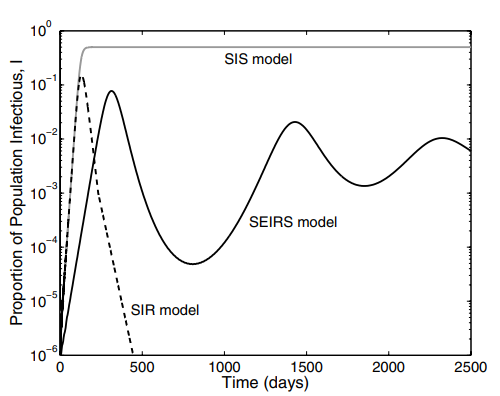

#### figura 3

La figura 3 nos muestra el comportamiento esperado de la poblacion de infectados en el modelo SEIRS (Curva negra) al comparar esta grafica con la generada por el modelo en la seccion 3.1 podemos obsevar que ambas curvas se corresponden, con esto podemos verificar que el modelo implementado se comporta de forma correcta.

### 4.2 Cambio entrada 

- **Entrada escalonada:**En el día 500 de la infección, se observa un brusco aumento en la población infectada, coincidiendo con un cambio repentino en el parámetro β del modelo epidemiológico. Este cambio sugiere la posible aparición o mutación de una cepa más contagiosa del patógeno. Además, el aumento en el número de infectados conduce a una convergencia más rápida de la población infectada. Esto se atribuye a la mayor tasa de transmisión de la nueva cepa, que acelera la propagación de la enfermedad y, en consecuencia, la velocidad a la que la población infectada alcanza su punto máximo.

- **Entrada sinusoidal:**El comportamiento estacionario representado por la onda sinusoidal indica que después del pico inicial, la población infectada disminuirá significativamente, lo que puede interpretarse como el declive del brote de la enfermedad en el escenario base. Sin embargo, es importante tener en cuenta que, aunque la cantidad de individuos infectados disminuirá, la enfermedad no se erradica por completo en el corto plazo. Es posible que haya fluctuaciones o pequeños repuntes en el número de casos, dependiendo de varios factores como las medidas de control implementadas y la inmunidad de la población.

- **Entrada pulso: **los pulsos que simulan cuarentenas periódicas, donde la población es sometida a períodos de restricción. En un año hipotético, por ejemplo, se establecen 23 días de cuarentena y 27 días sin restricciones. Se observa que estas cuarentenas son efectivas, ya que durante los períodos de restricción, la población infectada disminuye notablemente. Este patrón demuestra la importancia de las cuarentenas en la contención de la propagación de patógenos infecciosos y, en última instancia, en la salvaguarda de vidas. La reducción en el número de infectados durante los períodos de cuarentena indica que estas medidas son eficaces para controlar la transmisión del virus y evitar una mayor propagación de la enfermedad. 

### 4.3 Varaiacion de Parametros

#### 4.3.1 Soluciones cambiando ν

Para valores más pequeños de `ν`, que representan la tasa de pérdida de inmunidad, la población experimentará valles más pronunciados en la curva de susceptibles. Esto se debe a que los individuos recuperados retienen su inmunidad por más tiempo, lo que significa que menos individuos regresan al compartimento susceptible. Como resultado, la población susceptible tarda más en estabilizarse durante la fase de recuperación de un brote de enfermedad.

#### 4.3.2 Soluciones  cambiando γ

Cuando `ν` es pequeño y γ aumenta, muchos individuos se recuperan simultáneamente, lo que provoca una disminución brusca de la población infectada y un aumento repentino de la población recuperada. Este rápido cambio puede prolongar el tiempo necesario para que la población se estabilice, ya que la transición de individuos desde el estado infectado al recuperado ocurre de manera rápida.

## 5. Referencias

- [1]       K. Rock, S. Brand, J. Moir, and M. J. Keeling, ‘Dynamics of infectious diseases’, Reports on Progress in Physics, vol. 77, no. 2, p. 026602, Jan. 2014.

- [2]  O. N. Bjørnstad, K. Shea, M. Krzywinski, and N. Altman, ‘The SEIRS model for infectious disease dynamics’, Nature Methods, vol. 17, no. 6, pp. 557–558, Jun. 2020.

- [3]  T. Tomé and M. de Oliveira, ‘Susceptible-infected-recovered and susceptible-exposed-infected models’, J. Phys. J. Phys. A: Math. Theor, vol. 16750, 03 2011.

- [4]        Bill & Melinda Gates Foundation. “SEIR and SEIRS Models — HIV Model Documentation.” *Docs.idmod.org*, docs.idmod.org/projects/emod-hiv/en/latest/model-seir.html. Accessed 14 Apr. 2024.